# HRV Analysis

## Dependencies

- [PhysioNet Cardiovascular Signal Toolbox](https://github.com/cliffordlab/PhysioNet-Cardiovascular-Signal-Toolbox)

## Setup

% Current working directory should be stress_and_addiction
addpath(genpath('../PhysioNet-Cardiovascular-Signal-Toolbox'))
addpath('../stress_and_addiction')
startup

Adding the PhysioNet Cardiovascular Signal Toolbox to Matlab path
PhysioNet Cardiovascular Signal Toolbox successfully added to Matlab path


## Experiments

### Reading Participants Data



------------------------------------------

-= Reading ID: 010017 =-
  > loading ...  > done ...

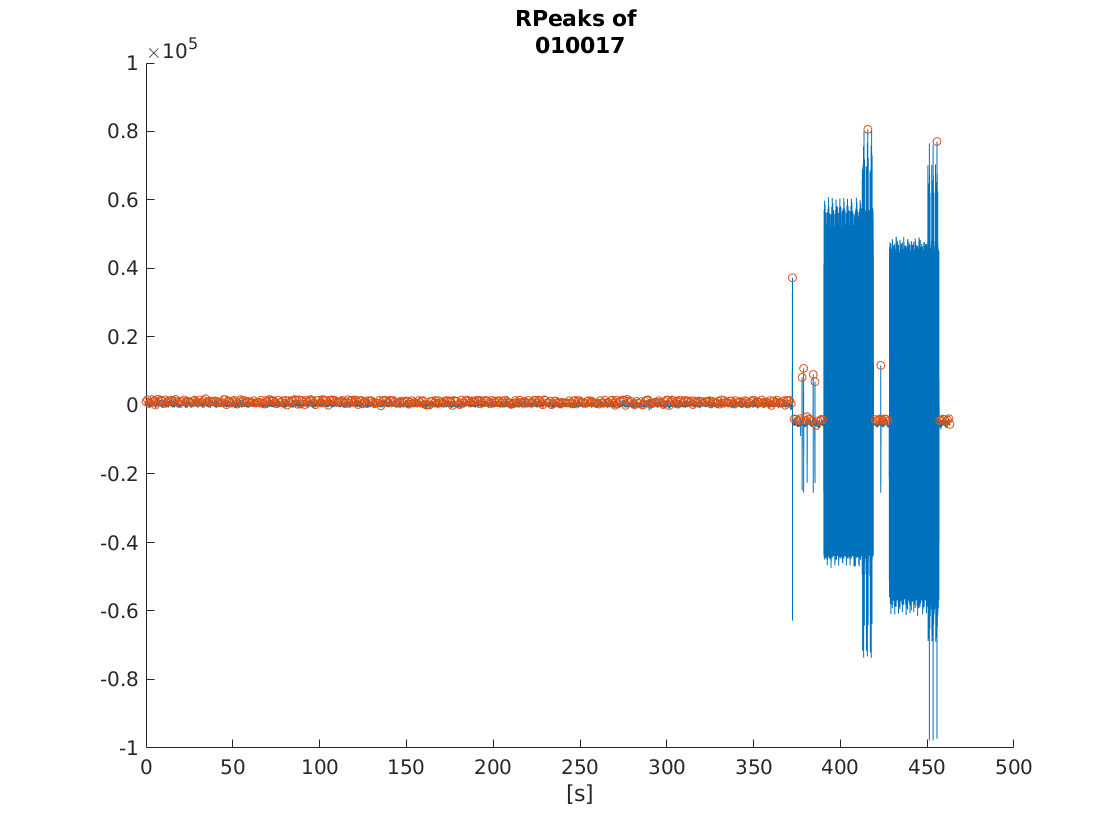

		BPM : 61.286
		AVNN : 981.044
		SDNN : 1711.069
		RMSSD : 1970.788
		SDANN : 316.259
		SDNNi : 1690.642




------------------------------------------

-= Reading ID: 010015 =-
  > loading ...  > done ...

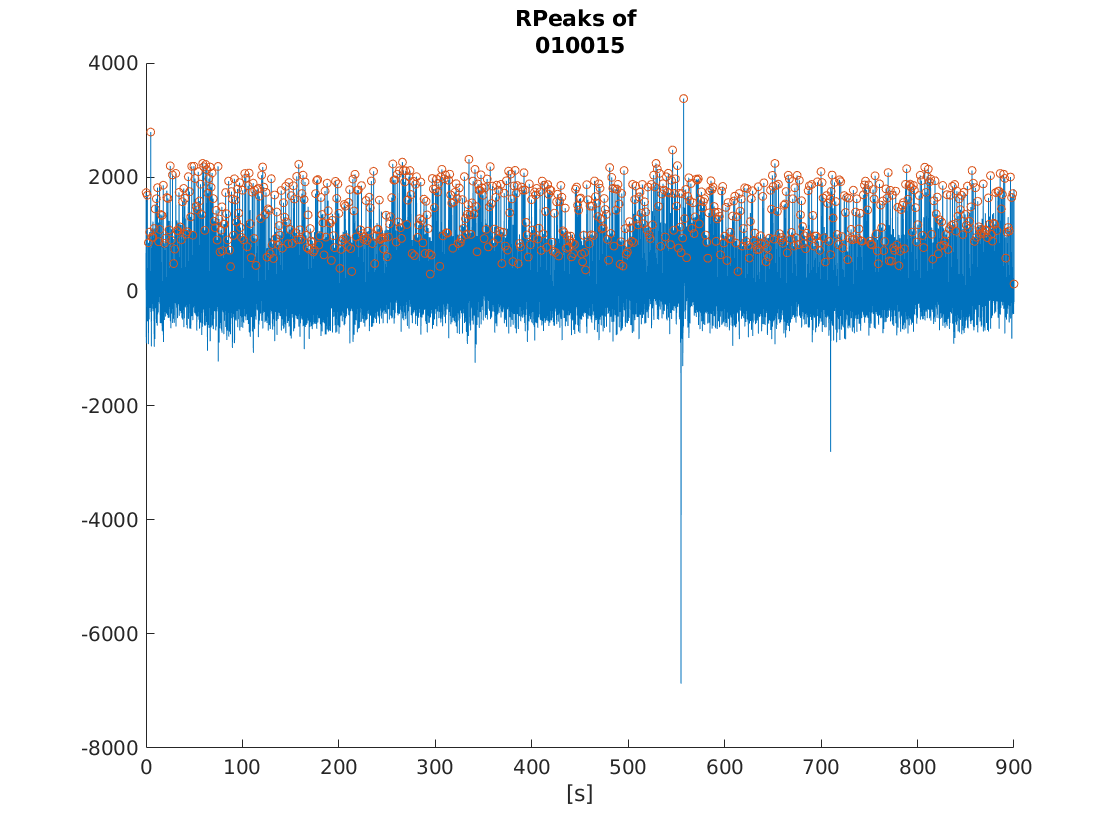

		BPM : 53.600
		AVNN : 1120.567
		SDNN : 87.607
		RMSSD : 1123.982
		SDANN : 25.678
		SDNNi : 84.872




------------------------------------------

-= Reading ID: 010010 =-
  > loading ...  > done ...

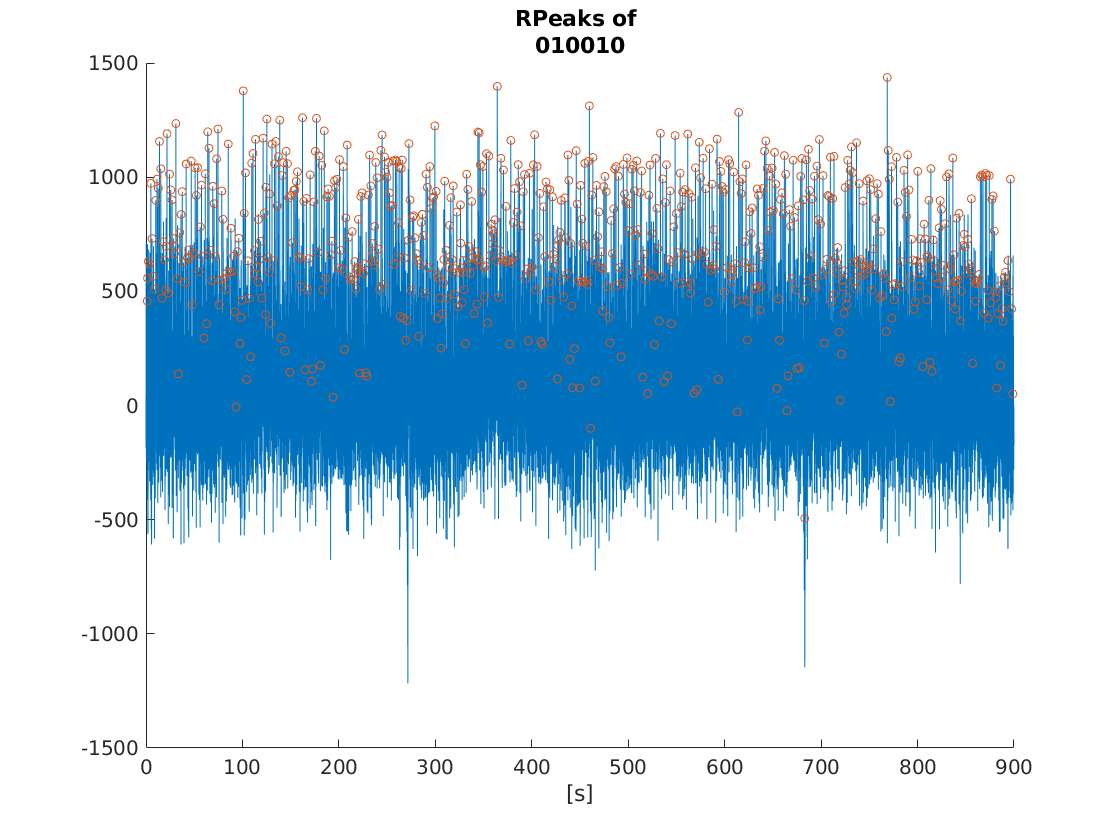

		BPM : 50.267
		AVNN : 1191.997
		SDNN : 273.346
		RMSSD : 1222.897
		SDANN : 34.671
		SDNNi : 270.827




------------------------------------------

-= Reading ID: 010020 =-
  > loading ...  > done ...

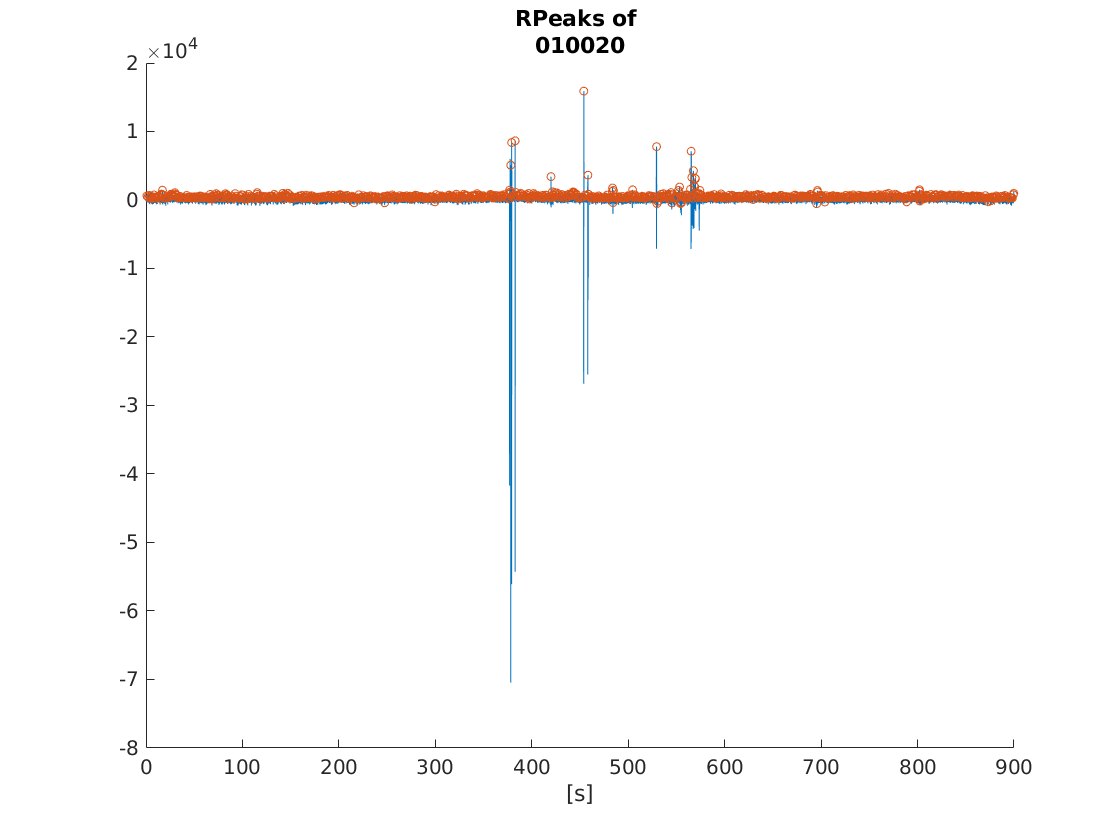

		BPM : 65.267
		AVNN : 919.064
		SDNN : 201.386
		RMSSD : 940.848
		SDANN : 39.483
		SDNNi : 193.753




------------------------------------------

-= Reading ID: 010134 =-
  > loading ...  > done ...

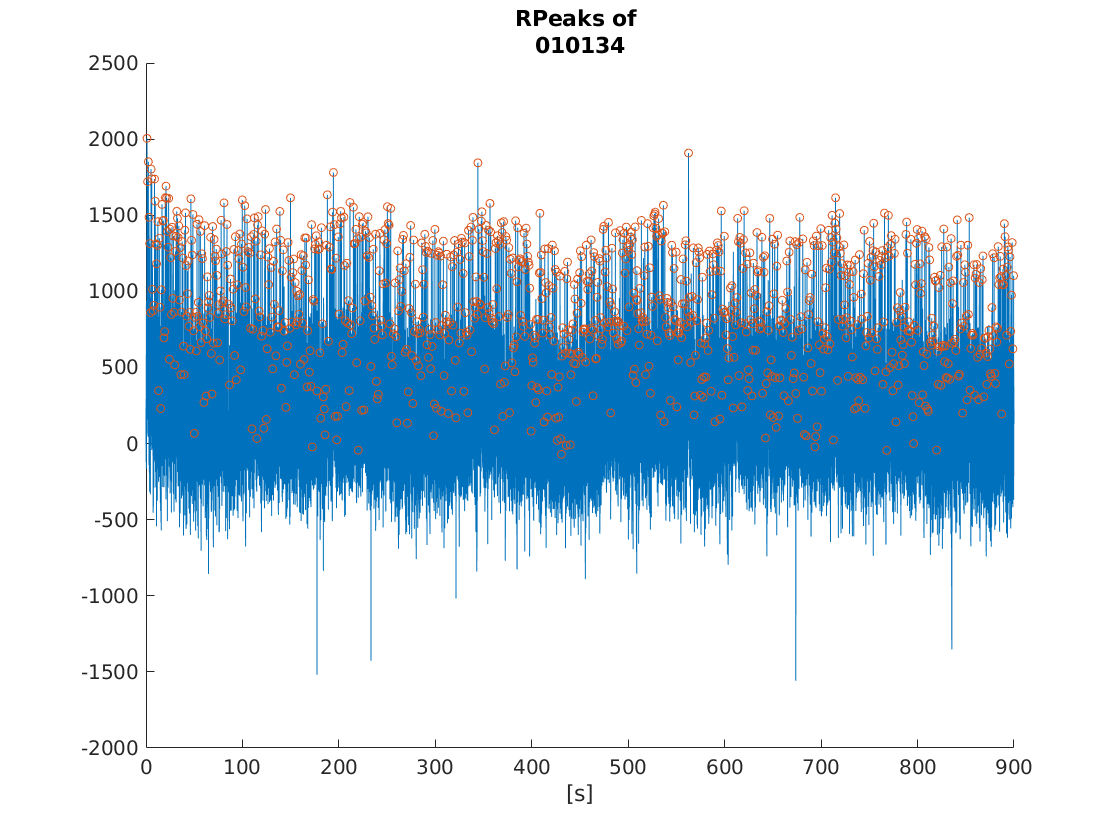

		BPM : 78.733
		AVNN : 761.477
		SDNN : 79.112
		RMSSD : 765.572
		SDANN : 30.052
		SDNNi : 74.829




------------------------------------------

-= Reading ID: 010227 =-
  > loading ...  > done ...

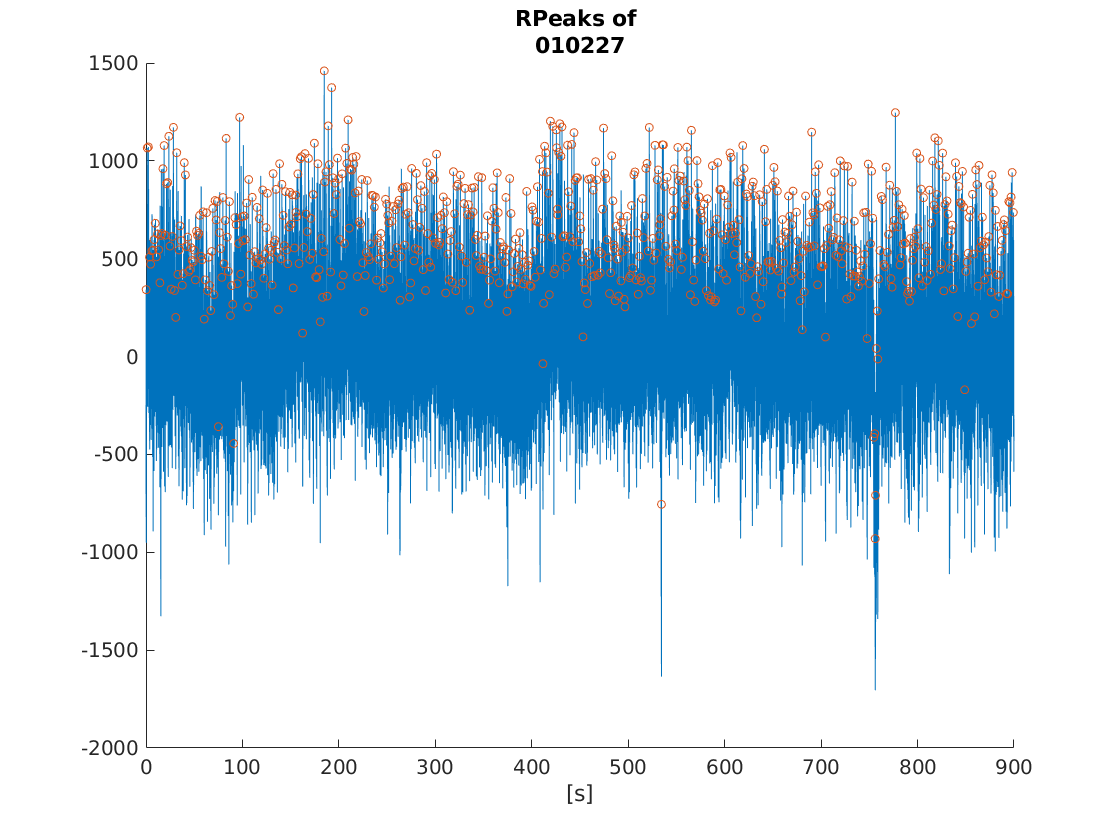

		BPM : 52.533
		AVNN : 1142.548
		SDNN : 140.601
		RMSSD : 1151.155
		SDANN : 23.048
		SDNNi : 137.848




------------------------------------------

-= Reading ID: 010084 =-
  > loading ...  > done ...

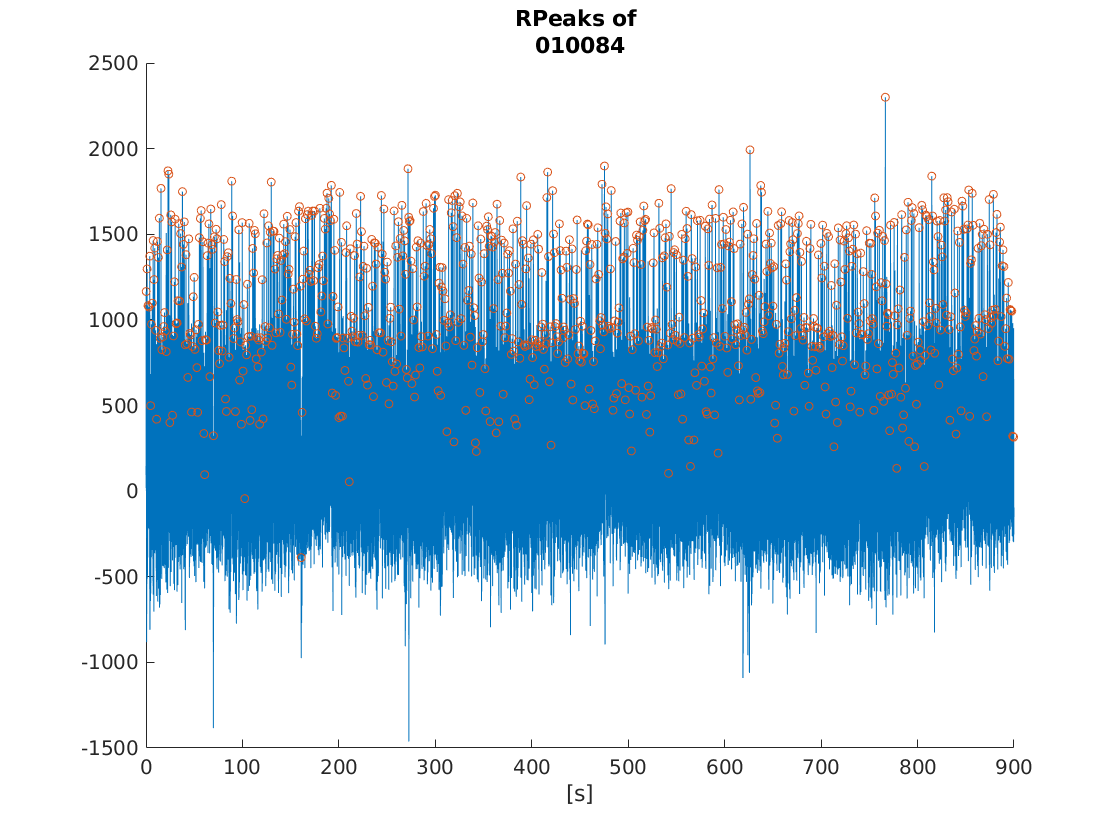

		BPM : 67.000
		AVNN : 895.832
		SDNN : 57.779
		RMSSD : 897.691
		SDANN : 15.628
		SDNNi : 55.702




------------------------------------------

-= Reading ID: 010003 =-
  > loading ...  > done ...

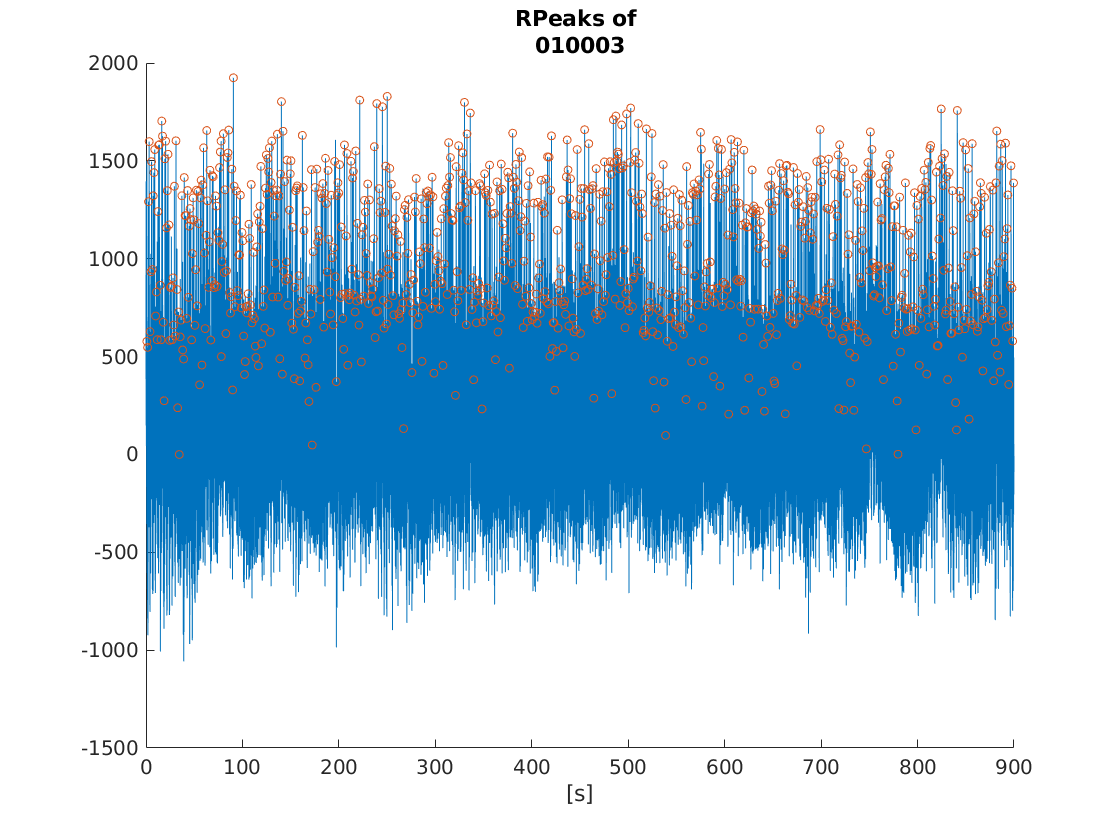

		BPM : 71.133
		AVNN : 843.006
		SDNN : 71.683
		RMSSD : 846.045
		SDANN : 8.130
		SDNNi : 69.755




------------------------------------------

-= Reading ID: 010028 =-
  > loading ...  > done ...

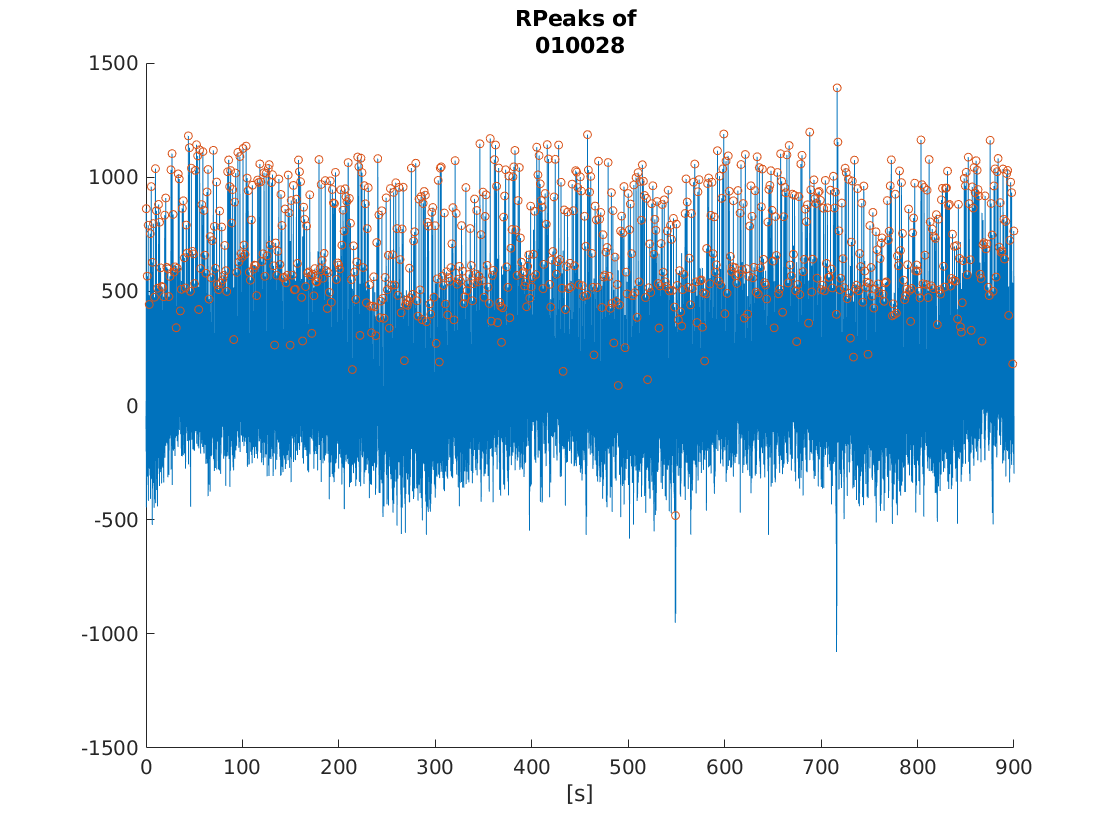

		BPM : 55.400
		AVNN : 1083.757
		SDNN : 81.009
		RMSSD : 1086.776
		SDANN : 19.527
		SDNNi : 78.573




------------------------------------------

-= Reading ID: 010079 =-
  > loading ...  > done ...

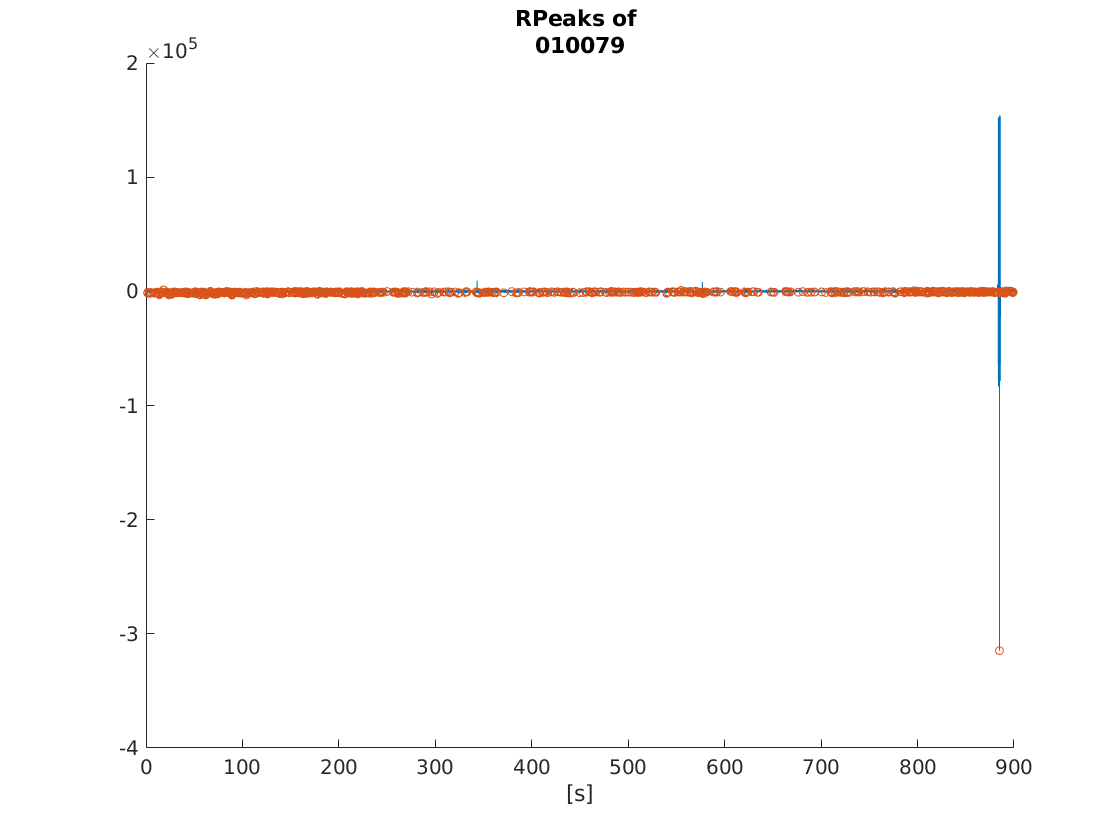

		BPM : 49.467
		AVNN : 1211.225
		SDNN : 1473.240
		RMSSD : 1906.456
		SDANN : 447.463
		SDNNi : 1449.132


GroupA = ["010017", "010015", "010010", "010020", "010134"]; % up
GroupB = ["010227", "010084", "010003", "010028", "010079"]; % down
Groups = {GroupA; GroupB};

hrv_struct = InitializeHRVResults();

results = cell(1, length(Groups));
for gid = 1 : length(Groups)
    fprintf('\n========================================================\n')
    currentGroup = Groups{gid};
    
    group_result = arrayfun(@(x)hrv_struct,1:length(currentGroup));
    for pid = 1 : length(currentGroup)  
        subID = currentGroup(pid);
        ecgData = sad.read_participant_data(subID);
        ecgData = ecgData(1:min(length(ecgData),9e5));  % clip to 15 minutes only or max data length
        
        hrv = hrv_analysis_time_domain(ecgData, subID);
        PrintReport(hrv);
        group_result(pid) = hrv;
    end
    
    results{gid} = group_result;
end

results{1}.SDANN

ans = 316.2590

ans = 25.6780

ans = 34.6709

ans = 39.4830

ans = 30.0525


x = 1;
y = results{1}.SDANN;
g = {hospital.Sex,hospital.Smoker};
gscatter(x,y,g,'rkgb','o*',8,'on','Age','Weight')
legend('Location','northeastoutside')


### Analyzing Single Participant

ecgData = sad.read_participant_data("010079");



------------------------------------------

-= Reading ID: 010079 =-
  > loading ...  > done ...

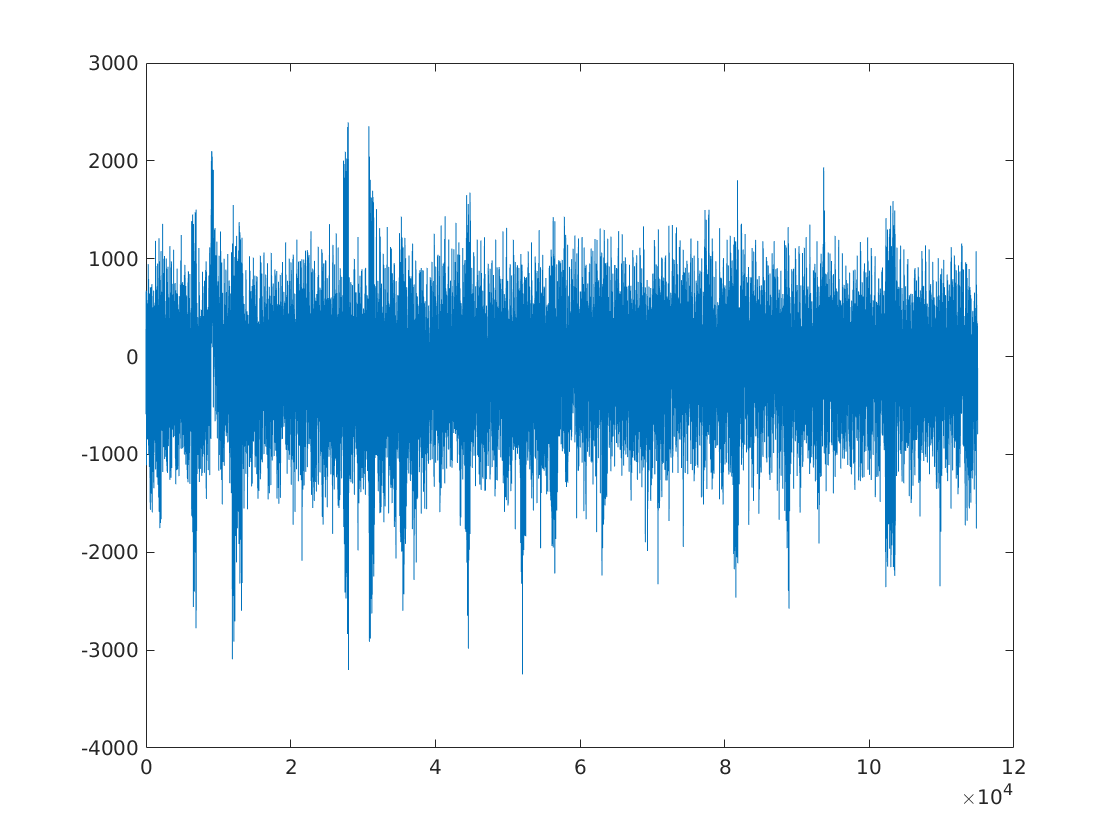

X = ecgData(1:2:end/4);
% lower sample rate
figure;
plot(X);


Fs = 500;             % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(X);        % Length of signal
t = (0:L-1)*T;        % Time vector

Y = fft(X, L);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

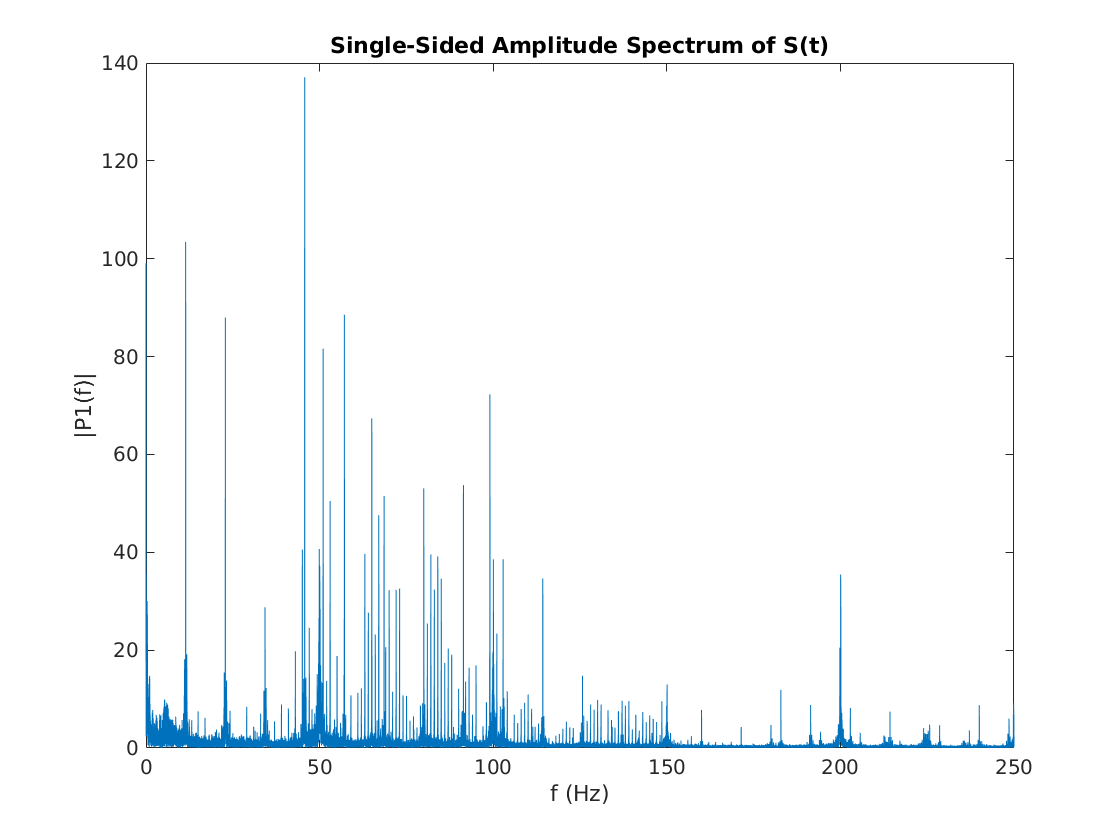

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;

figure;
plot(f,P1) 
title('Single-Sided Amplitude Spectrum of S(t)')
xlabel('f (Hz)')
ylabel('|P1(f)|')

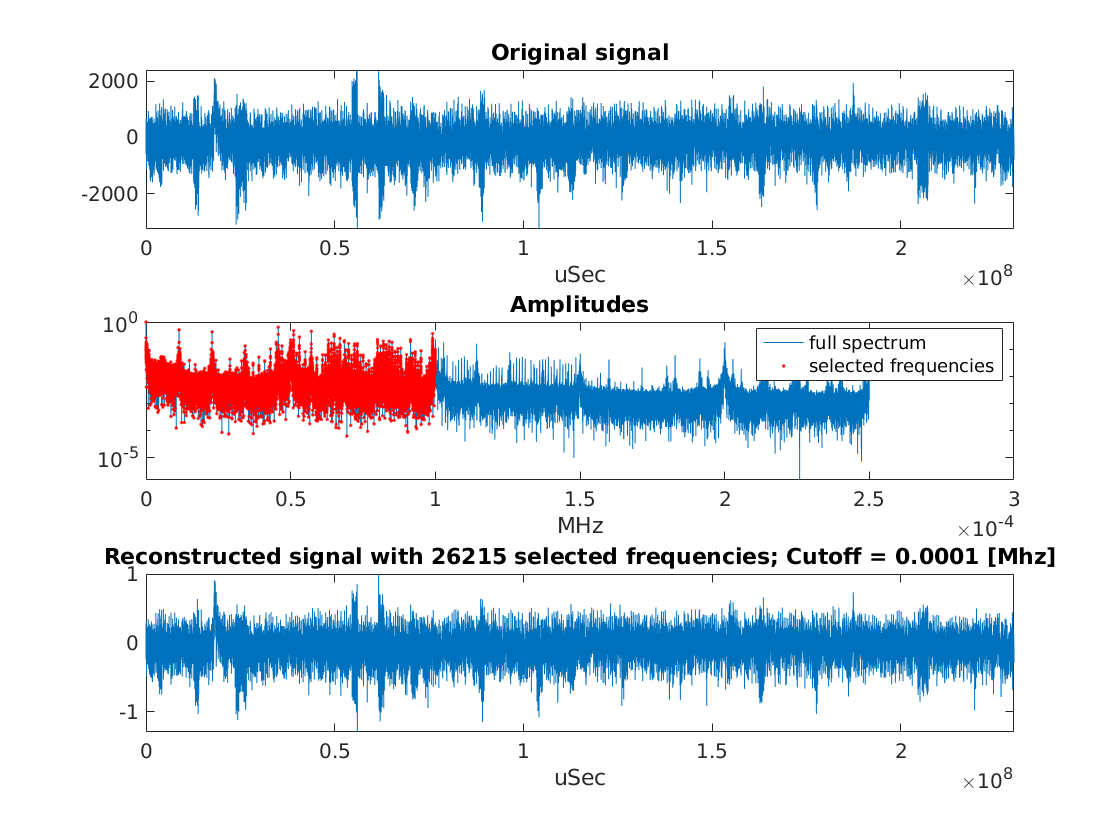

figure;
fftf(t, X, 1e2);

## Functions

function hrvResults = InitializeHRVResults() 

    %% TIME DOMAIN
    
    hrvResults.BPM = 0;
    hrvResults.RR_interval=0;
    hrvResults.AVNN=0;
    hrvResults.SDNN=0;
    hrvResults.RMSSD=0;
    hrvResults.SDANN=0;
    hrvResults.SDNNi=0;
    
end

function PrintReport(hrvResult) 
    fprintf('\t\tBPM : %.3f\n', hrvResult.BPM);
    fprintf('\t\tAVNN : %.3f\n', hrvResult.AVNN);
    fprintf('\t\tSDNN : %.3f\n', hrvResult.SDNN);
    fprintf('\t\tRMSSD : %.3f\n', hrvResult.RMSSD);
    fprintf('\t\tSDANN : %.3f\n', hrvResult.SDANN);
    fprintf('\t\tSDNNi : %.3f\n', hrvResult.SDNNi);
end


function hrv = hrv_analysis_time_domain(ecgData, subID)
%%%
% SDNN	ms	                 Standard deviation of NN intervals
% SDANN	ms	                 Standard deviation of the average NN intervals for each 5 min segment of a 24 h HRV recording
% SDNN index (SDNNI)	ms	 Mean of the standard deviations of all the NN intervals for each 5 min segment of a 24 h HRV recording
% pNN50	%	                 Percentage of successive RR intervals that differ by more than 50 ms
% HR Max − HR Min	bpm	 Average difference between the highest and lowest heart rates during each respiratory cycle
% RMSSD	ms	                 Root mean square of successive RR interval differences
%
    Fs = 1000;
    
    HRVparams = InitializeHRVparams('lemon-dataset');
    HRVparams.Fs = 1000;
    r_peaks = jqrs(ecgData, HRVparams);
    
    % plot
    figure;
    hold on;
    sad.plot_ecg_waveform(ecgData)
    plot(r_peaks./Fs, ecgData(r_peaks),'o');
    title(['RPeaks of ', subID])
    hold off;
    
    hrv.BPM = length(r_peaks)/(length(ecgData)/Fs/60);
    RR_interval = r_peaks(2:end) - r_peaks(1:end-1);
    hrv.RR_interval = RR_interval;
    hrv.AVNN = mean(RR_interval);
    hrv.SDNN = std(RR_interval);
    hrv.RMSSD = sqrt(mean(RR_interval.*RR_interval));
    
    window_size = 5*60*Fs;
    bin_of_5_mins = 0:window_size:(ceil(length(ecgData)/window_size)*window_size);
    
    [~, binId] = histc( r_peaks, bin_of_5_mins ) ;
    grouped = accumarray( binId', r_peaks, [], @(v){v} );
    mean_arr = (1: length(grouped));
    std_arr = (1: length(grouped));
    for i = 1: length(grouped)
        r_peaks_in_window = cell2mat(grouped(i));
        rr_intervals_in_window = r_peaks_in_window(2:end) - r_peaks_in_window(1:end-1);
        mean_arr(i) = mean(rr_intervals_in_window);
        std_arr(i) = std(rr_intervals_in_window);
    end
    
    hrv.SDANN = std(mean_arr);
    hrv.SDNNi = mean(std_arr);
end

function [X, f, y, y2] = fftf(t, x, varargin)
% fftf - fft filter;
%   [X, f, y, y2] = fftf(t, x); with t the time vector and x the signal,
%   displays the original signal, the Fourier transform (absolute values)
%   and the reconstructed signal generated by the inverse transform ifft
%   with a selected subset of the frequencies.
%   By default, the frequencies in the filtered signal are cut at 1/8 the
%   sampling frequency.
%   The function returns X - reconstructed signal, f - vector of frequencies, y -
%   full vector of amplitudes, y2 - the filtered vector of amplitudes.
%   [X, f, y, y2] = fftf(t, x, cutoff); the user may set the cutoff
%   frequency in units of Hertz.
%   [X, f, y, y2] = fftf(t, x, cutoff, my_N); the user may select my_N
%   amplitudes with highest abolute value to participate in the
%   reconstruction.
%   Examples
%   (suppose you have t and x defined already, both 1-dimensional vectors of the same length.)
%   fftf(t, x, 1e6); - reconstruct the signal with frequencies lower or
%   equal to cutoff value of 1MHz.
%   fftf(t, x, [], 20); - use only 20 biggest amplitudes for
%   reconstruction.
%   fftf(t, x, 1e6, 20); - select 20 biggest amplitudes within cutoff.
% Shmuel Ben-Ezra, Ultrashape ltd. August 2009
%% Verifying input
    if ~any(size(t)==1)
       disp('Unexpected vector size! - should be 1D vectors.')
       return
    end
    if ~any(size(x)==1)
       disp('Unexpected vector size! - should be 1D vectors.')
       return
    end
    if length(t)~=length(x)
       disp('Unexpected vector size! - should be same length.')
       return
    end
    %% Definitions
    Fs=1/(t(2)-t(1)); %sampling freq
    N=length(x);
    Nfft=2^nextpow2(N);
    f=Fs/2*linspace(0,1,1+Nfft/2); % create freqs vector
    cutoff_freq=Fs/8;
    my_freqs=[];
    if nargin>2
        cutoff_freq=varargin{1};
    end
    if nargin>3
        my_freqs=varargin{2};
    end
    %% main
    y=fft(x,Nfft)/N; % perform fft transform
    y2=filterfft(f, y, cutoff_freq, my_freqs); % filter amplitudes
    %X=ifft(y2,'symmetric'); % the inverse transform. 'symmetric' is not recognized in older versions of matlab 
    X=ifft(y2); % inverse transform
    X=X(1:N)/max(X);
    ind1 = find(y2(1:1+Nfft/2)); % get the nonzero elements in y2
    nf1 = length(ind1); % count nonzero elements
    %% display
    figname = 'fftf - FFT at work';
    ifig = findobj('type', 'figure', 'name', figname);
    if isempty(ifig)
        ifig = figure('name', figname); % on my machine: ..., 'position', [360   120   600   800]);
    end
    figure(ifig);
    % first plot
    subplot(3,1,1)
    plot(t*1e6,x)
    xlabel('uSec')
    axis tight
    title('Original signal')
    %second plot
    subplot(3,1,2)
    yplot=abs(y(1:1+Nfft/2));
    yplot=yplot/max(yplot);
    semilogy(f*1e-6, yplot, f(ind1)*1e-6, yplot(ind1), '.r');
    xlabel('MHz')
    title('Amplitudes')
    legend('full spectrum', 'selected frequencies')
    % third plot
    subplot(3,1,3)
    plot(t*1e6,X)
    xlabel('uSec')
    if isempty(cutoff_freq)
        scutoff='No cutoff.';
    else
        scutoff=sprintf('Cutoff = %g [Mhz]', cutoff_freq/1e6);
    end
    stitle3=sprintf('Reconstructed signal with %d selected frequencies; %s', nf1, scutoff);
    title(stitle3)
    axis tight
    return
end

function y2=filterfft(f, y, cutoff, wins)
    nf=length(f);
    ny=length(y);
    if ~(ny/2+1 == nf)
        disp('unexpected dimensions of input vectors!')
        y2=-1;
        return
    end
    % cutoff filter
    y2=zeros(1,ny);
    if ~isempty(cutoff)
        ind1=find(f<=cutoff);
        y2(ind1) = y(ind1); % insert required elements
    else
        y2=y;
    end
    % dominant freqs filter
    if ~isempty(wins)
        temp=abs(y2(1:nf));
        y2=zeros(1,ny);
        for k=1:wins   % number of freqs that I want
            [~, tmaxi]=max(temp);
            y2(tmaxi) = y(tmaxi); % insert required element
            temp(tmaxi)=0; % eliminate candidate from list
        end
    end
    % create a conjugate symmetric vector of amplitudes
    for k=nf+1:ny
        y2(k) = conj(y2(mod(ny-k+1,ny)+1)); % formula from the help of ifft
    end
    return
end